## Data Evaluation

data_path = 'C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\'

data_path = 'C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\'

save_path="C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\figures";

% Dominant frequencies in each experiment
% Organized to where experiment_5(i) = dominant frequency of subject i.
[exp_5_freqs, exp_5_amps] = data_eval(data_path, "05", "F8");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s05_ex05.mat


[exp_6_freqs, exp_6_amps] = data_eval(data_path, "06", "F8");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex06.mat


[exp_7_freqs, exp_7_amps] = data_eval(data_path, "07", "F8");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex07.mat


### Now that we have data gathered, we can pretty much do whatever we want.

One of the things we should consider is to obtain a *single* dominant frequency for each experiment. One metric we can use to obtain this is to consider the relative amplitudes of each peak.

We can use a 3d array here.

dominant_freqs = zeros(20,1,3);
dominant_freqs(:, 1, 1) = max(exp_5_freqs .* (max(exp_5_amps, [], 2) == exp_5_amps), [], 2);
dominant_freqs(:, 1, 2) = max(exp_6_freqs .* (max(exp_6_amps, [], 2) == exp_6_amps), [], 2);
dominant_freqs(:, 1, 3) = max(exp_7_freqs .* (max(exp_7_amps, [], 2) == exp_7_amps), [], 2);

### Removing messed up data (data segmented incorrectly)

Removing data from subject 5, experiment 5, and subject 3, experiment 6 and 7.

Also cutting out s07, s16, s18, s20

dominant_freqs_trimmed = cat(2, dominant_freqs(cat(2, 1:4, 6, 8:15, 17, 19), 1, 1), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 2), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 3));

Boxplots

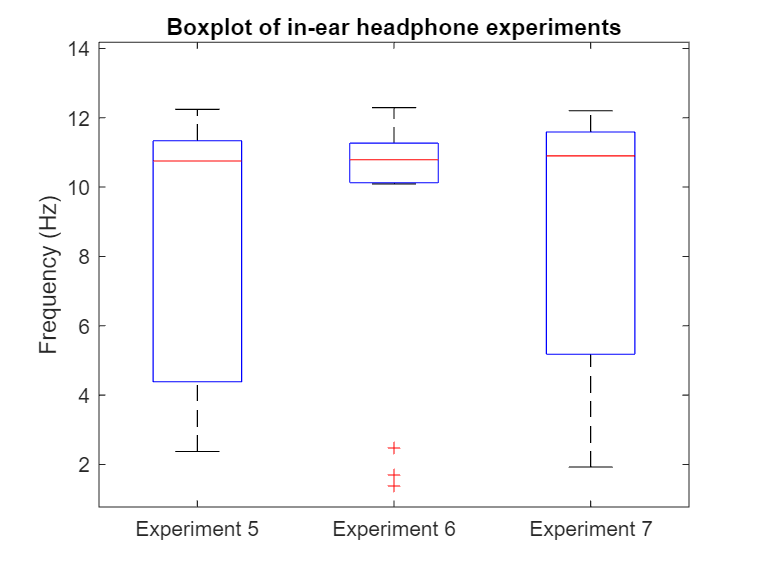

figure;
boxplot(dominant_freqs_trimmed);
xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Boxplot of in-ear headphone experiments")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "boxplot.png");
saveas(gcf, fig_path);

p-values, peforming t-test between datasets

% for i=1:size(dominant_freqs, 2)
%     freqs = dominant_freqs(:, i);
%     f = figure;
% end
for i=1:size(dominant_freqs_trimmed, 2)
    freqs = dominant_freqs_trimmed(:, i);
    f = figure;
    for j=1:size(dominant_freqs_trimmed, 2)
        if (i ~= j)
            comp_freqs = dominant_freqs_trimmed(:, j);
            [~, p] = ttest(freqs, comp_freqs);
            disp(strcat("Comparing ", num2str(i), " and ", num2str(j)));
            disp(num2str(p));
        end
    end
end

Comparing 1 and 2


0.75559


Comparing 1 and 3


0.93317


Comparing 2 and 1


0.75559


Comparing 2 and 3


0.80174


Comparing 3 and 1


0.93317


Comparing 3 and 2


0.80174


### Same Experiment With Different Electrodes

With T7

[exp_5_freqs, exp_5_amps] = data_eval(data_path, "05", "T7");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s05_ex05.mat


[exp_6_freqs, exp_6_amps] = data_eval(data_path, "06", "T7");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex06.mat


[exp_7_freqs, exp_7_amps] = data_eval(data_path, "07", "T7");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex07.mat



dominant_freqs = zeros(20,1,3);
dominant_freqs(:, 1, 1) = max(exp_5_freqs .* (max(exp_5_amps, [], 2) == exp_5_amps), [], 2);
dominant_freqs(:, 1, 2) = max(exp_6_freqs .* (max(exp_6_amps, [], 2) == exp_6_amps), [], 2);
dominant_freqs(:, 1, 3) = max(exp_7_freqs .* (max(exp_7_amps, [], 2) == exp_7_amps), [], 2);

dominant_freqs_trimmed = cat(2, dominant_freqs(cat(2, 1:4, 6, 8:15, 17, 19), 1, 1), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 2), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 3));

Analysis

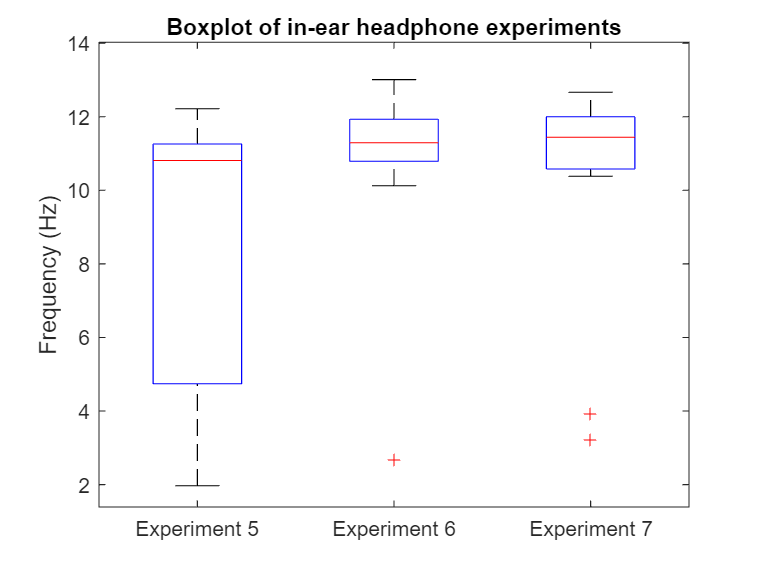

figure;
boxplot(dominant_freqs_trimmed);
xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Boxplot of in-ear headphone experiments")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "boxplot_t7.png");
saveas(gcf, fig_path);

for i=1:size(dominant_freqs_trimmed, 2)
    freqs = dominant_freqs_trimmed(:, i);
    f = figure;
    for j=1:size(dominant_freqs_trimmed, 2)
        if (i ~= j)
            comp_freqs = dominant_freqs_trimmed(:, j);
            [~, p] = ttest(freqs, comp_freqs);
            disp(strcat("Comparing ", num2str(i), " and ", num2str(j)));
            disp(num2str(p));
        end
    end
end

Comparing 1 and 2


0.034974


Comparing 1 and 3


0.051298


Comparing 2 and 1


0.034974


Comparing 2 and 3


0.70885


Comparing 3 and 1


0.051298


Comparing 3 and 2


0.70885


With midline

[exp_5_freqs, exp_5_amps] = data_eval(data_path, "05", "Cz");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s05_ex05.mat


[exp_6_freqs, exp_6_amps] = data_eval(data_path, "06", "Cz");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex06.mat


[exp_7_freqs, exp_7_amps] = data_eval(data_path, "07", "Cz");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex07.mat



dominant_freqs = zeros(20,1,3);
dominant_freqs(:, 1, 1) = max(exp_5_freqs .* (max(exp_5_amps, [], 2) == exp_5_amps), [], 2);
dominant_freqs(:, 1, 2) = max(exp_6_freqs .* (max(exp_6_amps, [], 2) == exp_6_amps), [], 2);
dominant_freqs(:, 1, 3) = max(exp_7_freqs .* (max(exp_7_amps, [], 2) == exp_7_amps), [], 2);

dominant_freqs_trimmed = cat(2, dominant_freqs(cat(2, 1:4, 6, 8:15, 17, 19), 1, 1), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 2), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 3));

Analysis

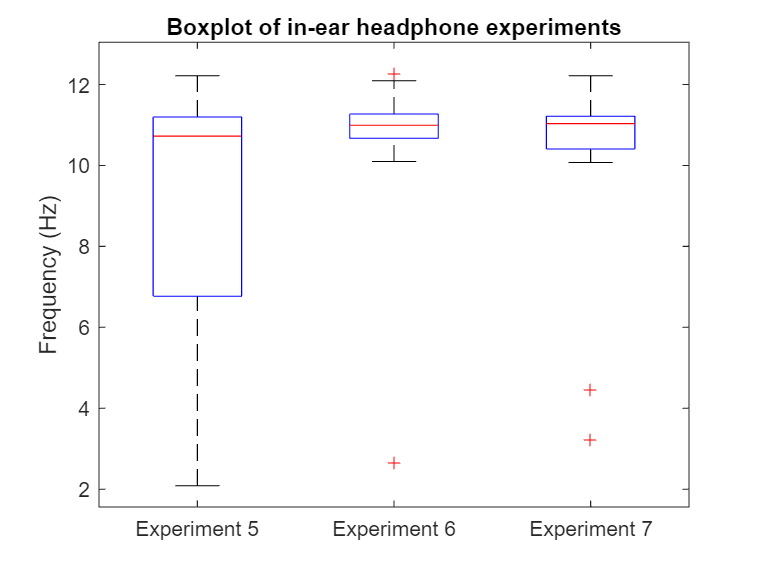

figure;
boxplot(dominant_freqs_trimmed);
xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Boxplot of in-ear headphone experiments")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "boxplot_cz.png");
saveas(gcf, fig_path);

for i=1:size(dominant_freqs_trimmed, 2)
    freqs = dominant_freqs_trimmed(:, i);
    f = figure;
    for j=1:size(dominant_freqs_trimmed, 2)
        if (i ~= j)
            comp_freqs = dominant_freqs_trimmed(:, j);
            [~, p] = ttest(freqs, comp_freqs);
            disp(strcat("Comparing ", num2str(i), " and ", num2str(j)));
            disp(num2str(p));
        end
    end
end

Comparing 1 and 2


0.071977


Comparing 1 and 3


0.10751


Comparing 2 and 1


0.071977


Comparing 2 and 3


0.64476


Comparing 3 and 1


0.10751


Comparing 3 and 2


0.64476
